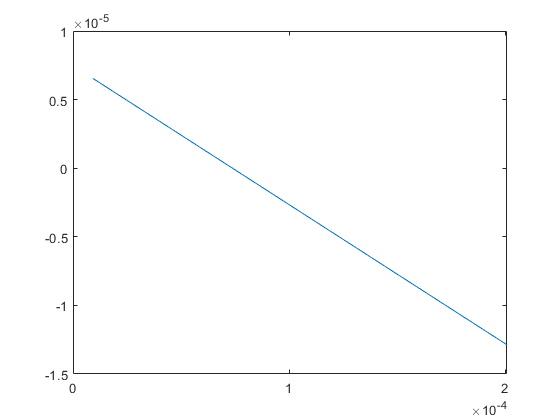

% B
% A  C
iA = 1;iB = 2; iC = 3;

Beacon = [
    30.511801,114.406786,43.2;
    30.511918,114.406791,43.2;
    30.511779,114.407003,43.2
];

Wid = 16 + 2 * 0.5;
High = 10 + 2 * 0.5;

Nx = 7; Ny = 5;
Testpoint_x = (0.7:2.5:Wid);
Testpoint_y = (0.7:2.5:High);

dx = (Beacon(iC, 1:2) - Beacon(iA, 1:2)) ./ Wid;
dy = (Beacon(iB, 1:2) - Beacon(iA, 1:2)) ./ High;

point_x = ones(Ny, Nx);
point_y = ones(Ny, Nx);

for j=1:Nx
    for i=1:Ny
        position = Testpoint_x(j) * dx + Testpoint_y(i) * dy;
        point_x(i,j) = position(2);
        point_y(i,j) = position(1);        
    end
end

figure
plot(point_x(1,:), point_y(1,:));

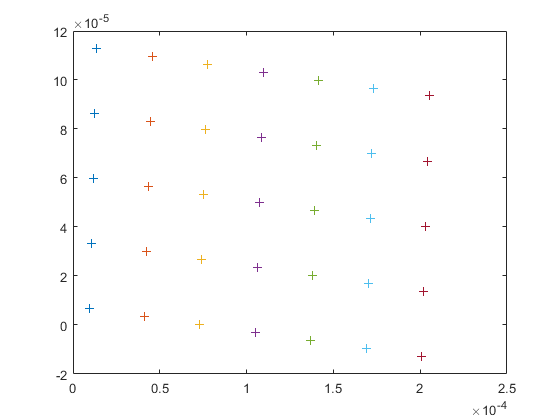

figure
plot(point_x, point_y,'+');

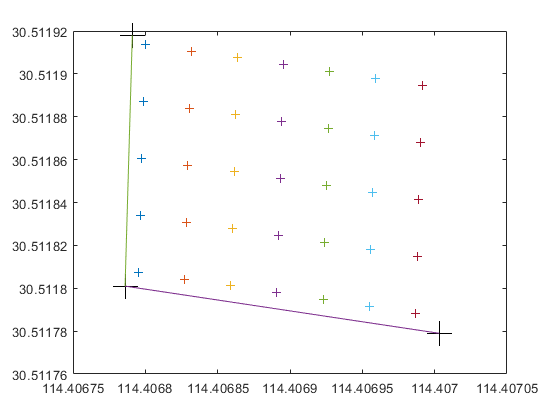


posx = Beacon(iA,2) + point_x;
posy = Beacon(iA,1) + point_y;

% pos
% x/y =
% 1   6   11 ...
% 2   7   12 ...
% 3   8   13 ...
% 4   9   14 ...
% 5   10  15 ...

postionAll = [(1:Nx*Ny)' posx(:) posy(:)];
dlmwrite('groundTurth.txt',postionAll,'delimiter','\t','precision', 18,'newline','pc');



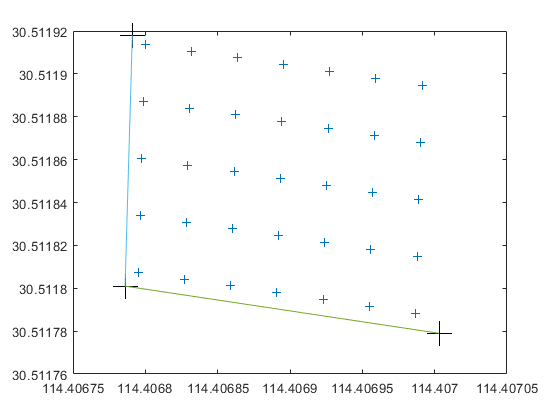

% figure
% plot(postionAll(:,2),postionAll(:,3),'+')
figure
plot(posx,posy,'+')
hold on
plot(Beacon(iA,2), Beacon(iA,1),'+k','MarkerSize',18);
hold on
plot(Beacon(iB,2), Beacon(iB,1),'+k','MarkerSize',18);
hold on
plot(Beacon(iC,2), Beacon(iC,1),'+k','MarkerSize',18);
hold on
plot(Beacon([iA iC],2), Beacon([iA iC],1))
hold on
plot(Beacon([iA iB],2), Beacon([iA iB],1))